# Experiment 3.1

## Name: John McAvoy

## Objectives

To learn to use MATLAB to

- Generate an LTI State-Space representation of a system

- Convert an LTI State-Space representation of a system to an LTI transfer function.

### Minimum Required Software Packages

MATLAB and the Control System Toolbox.

## Prelab

### Problem 1

*Derive the state-space representation of the translational mechanical system shown in Skill-Assesment Exercise 3.2 and provided below if you have not already done so. Consider the output ro be *$x_3(t)$*.*

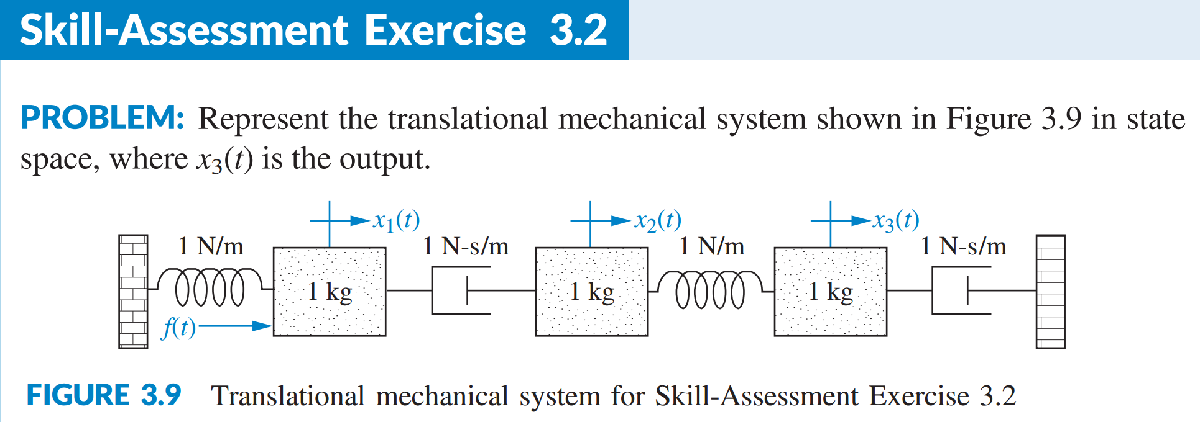

**Answer:**

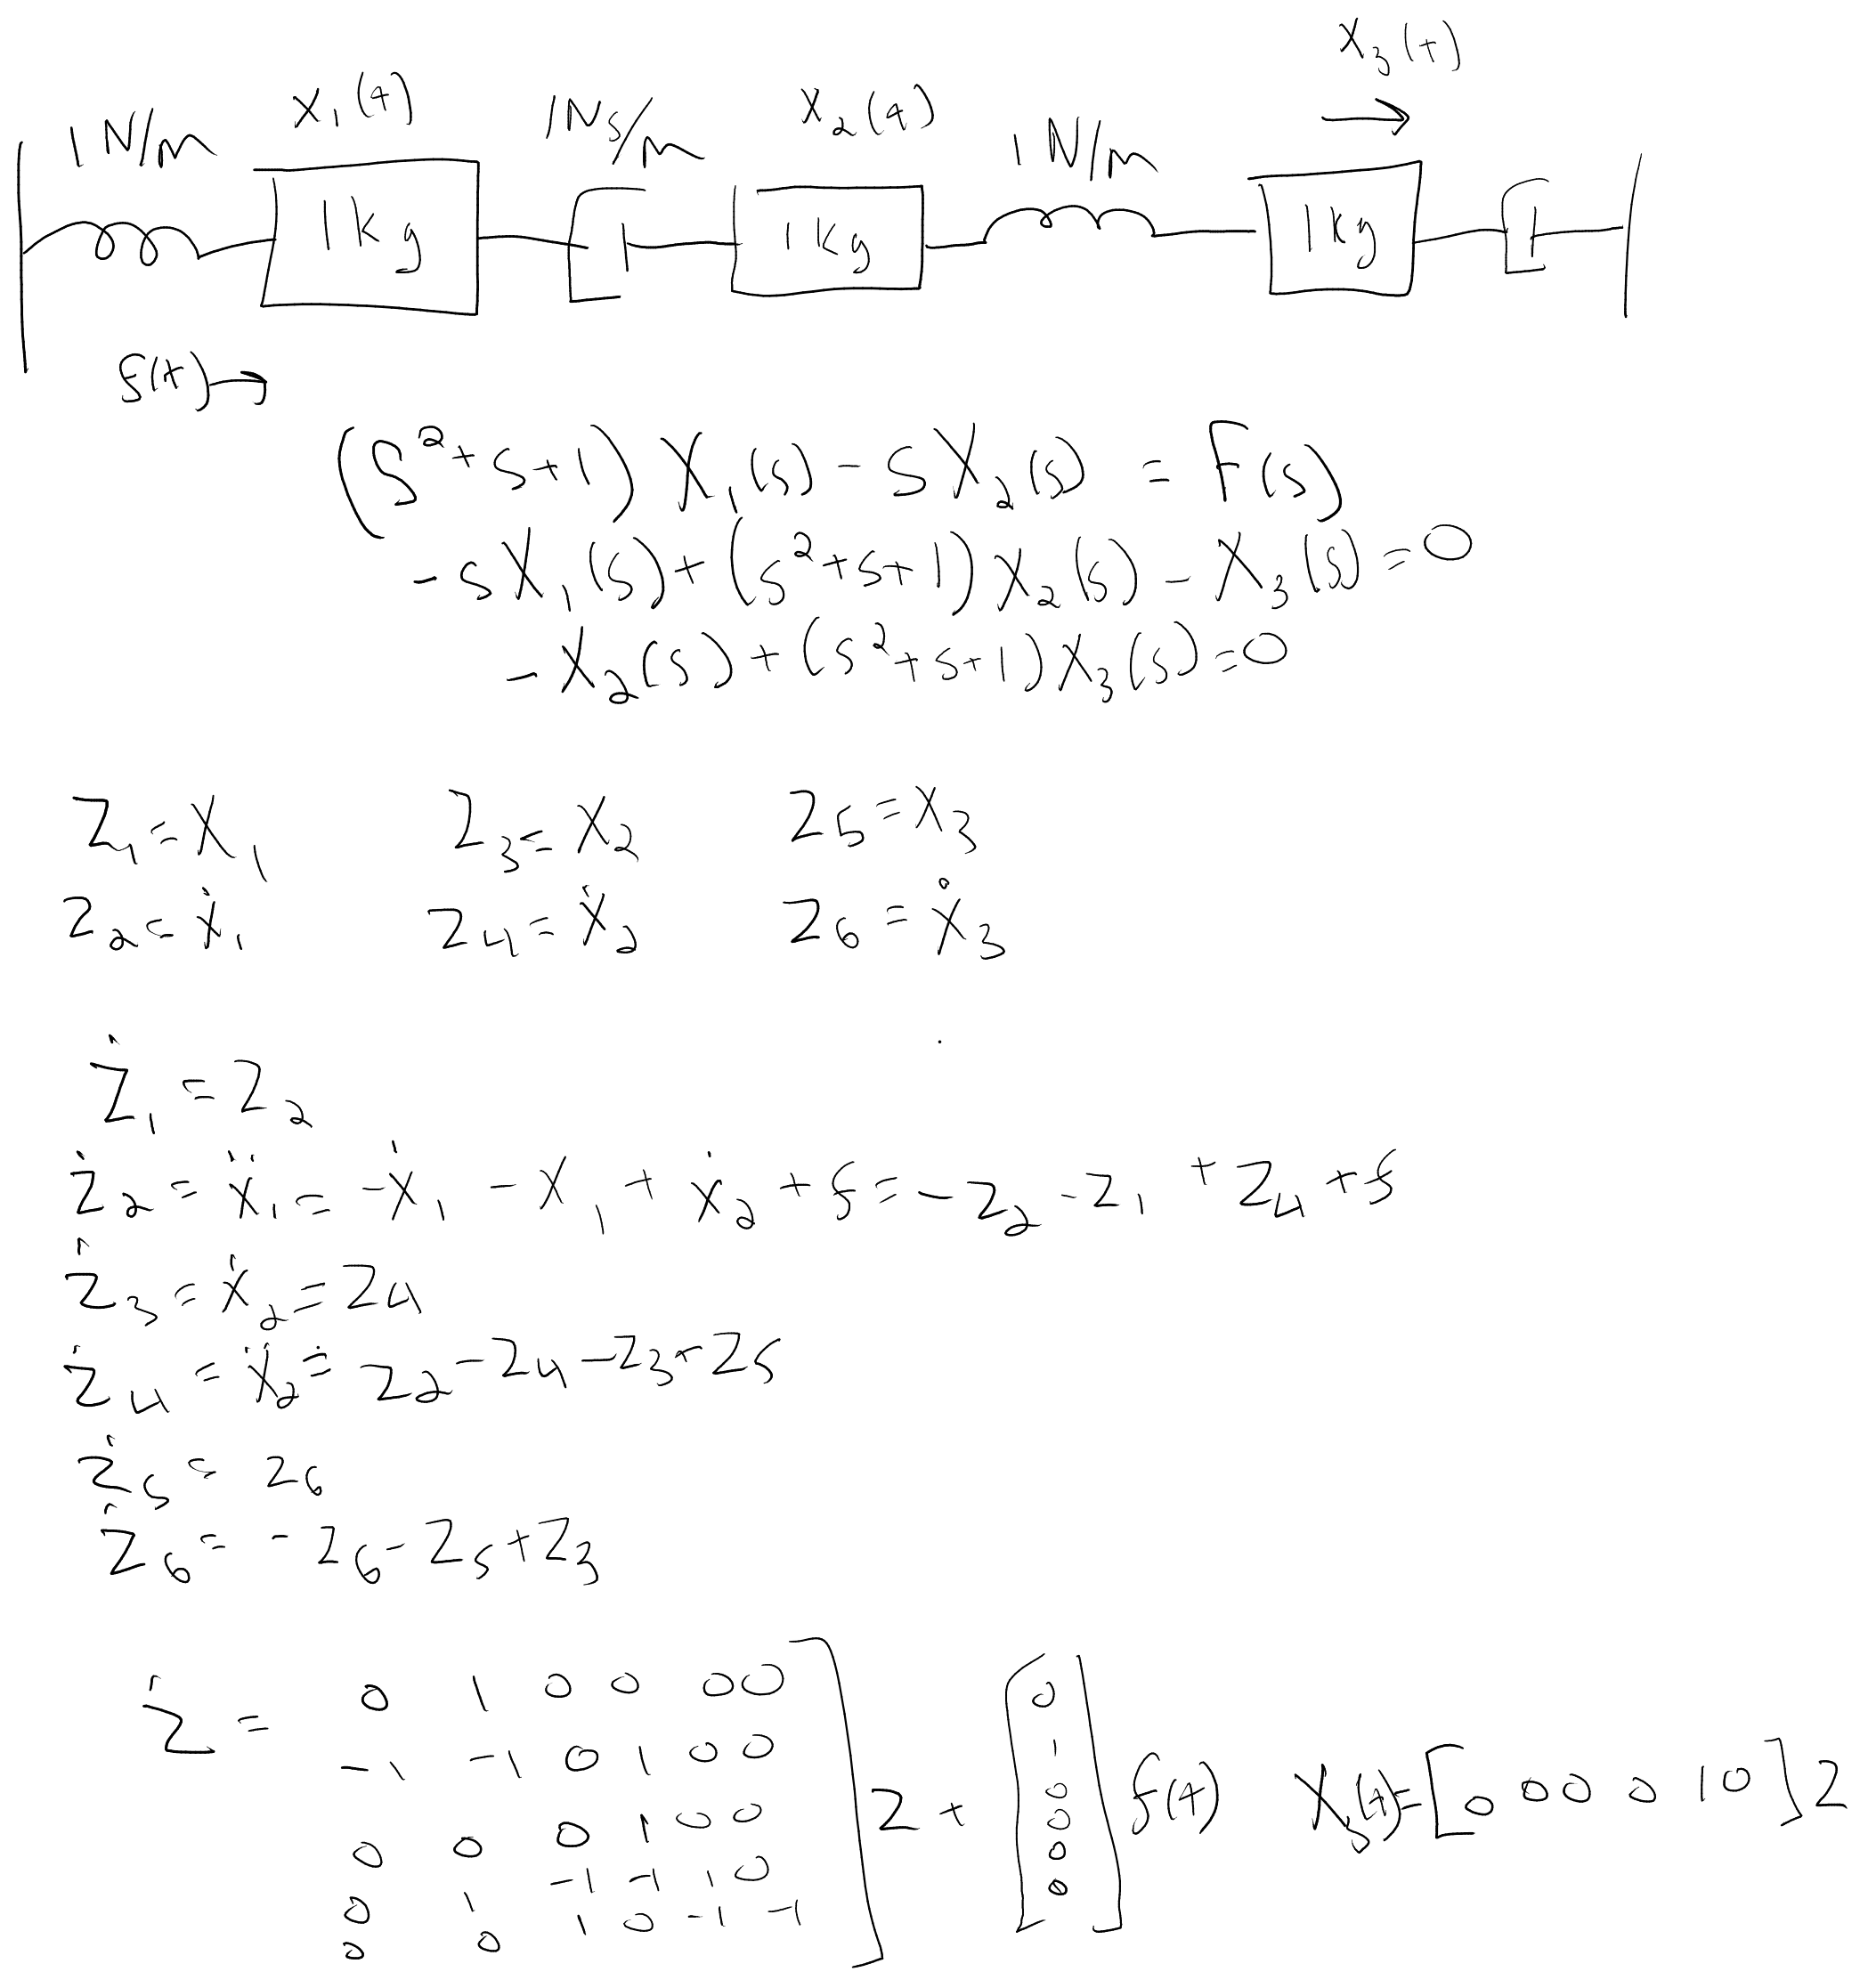

### Problem 2

*Derive the transfer function, *$\frac{X_3(s)}{F(s)}$*, from the equations of motion for the translational mechanical system shown above from Skill-Assessment Exercise 3.2.*

**Answer:**

## Lab

### Problem 1

*Use MATLAB to generate the LTI state-space representation derived in **Prelab 1**.*

A=[0 1 0 0 0 0;-1 -1 0 1 0 0;0 0 0 1 0 0;0 1 -1 -1 0;0 0 0 0 0 1;0 0 1 0 -1 -1]

A =      0     1     0     0     0     0
    -1    -1     0     1     0     0
     0     0     0     1     0     0
     0     1    -1    -1     1     0
     0     0     0     0     0     1
     0     0     1     0    -1    -1


B=[0;1;0;0;0;0]

B =      0
     1
     0
     0
     0
     0


C=[0 0 0 0 1 0]

C =      0     0     0     0     1     0


D=0

D = 0

sys=ss(A,B,C,D)


sys =
 
  A = 
       x1  x2  x3  x4  x5  x6
   x1   0   1   0   0   0   0
   x2  -1  -1   0   1   0   0
   x3   0   0   0   1   0   0
   x4   0   1  -1  -1   1   0
   x5   0   0   0   0   0   1
   x6   0   0   1   0  -1  -1
 
  B = 
       u1
   x1   0
   x2   1
   x3   0
   x4   0
   x5   0
   x6   0
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   0   0   0   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




ans =
 
                      s + 1.11e-16
  -----------------------------------------------------
  s^6 + 3 s^5 + 5 s^4 + 6 s^3 + 4 s^2 + 2 s + 6.177e-16
 
Continuous-time transfer function.



### Problem 2

*Use MATLAB to convert the LTI state-space representation found in **Lab 1** to the LTI transfer function found in **Prelab 2**.*

tf(sys)


ans =
 
                      s + 1.11e-16
  -----------------------------------------------------
  s^6 + 3 s^5 + 5 s^4 + 6 s^3 + 4 s^2 + 2 s + 6.177e-16
 
Continuous-time transfer function.



## Postlab

### Problem 1

*Compare your transfer functions as found from **Prelab 2** and **Lab 2**.*

**The transfer functions matched.**

### Problem 2

*Discuss the use of MATLAB to create LTI state-space representations and the use of MATLAB to convert these representations to transfer functions.*

**Creating LTI state-space representation in MATLAB is really easy using the **`ss`** function and then converting state-space's to transfer functions is as easy as passing the **`ss`** to **`tf`**.**